# Inner Controller Development

## Setup

% check to see if the quad_copter_models file already contains the controller info
% If that is the case maybe we need to regenerate it to account for changes in the 
% base data
if exist('quad_copter_models.mat', 'file')
    data = load('quad_copter_models.mat');
    if isfield(data, 'OptimalInnerController')
        fprintf('Detected previous model data. Moving it to ''quad_copter_models_old.mat''');
        movefile('quad_copter_models.mat', 'quad_copter_models_old.mat');        
    end

    clear data;
end
  
run mk_quad_copter_models.m;    
load 'quad_copter_models.mat';


We want to develop the fastest controller for the system that we can possibly get. This is a two step process. First we increase the bandwidth of the innner system to the limit and then work on the outer controller. Before we start we need to devise a reference model.

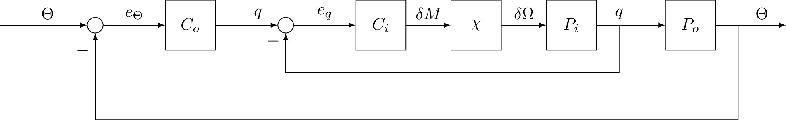

We have a set of I/O data measured from the input of the `PitchRateModel` block to it's output. The input is $\delta \Omega$ is the difference between the speeds of the front and rear propellers. For more information on the origin of this choice read [this](http://thesis.comkieffer.com/making-sense-of-the-data.html) article. Since writing that article the data has been processed to convert it to absolute values. The output of the `PitchRateModel` block is the angular velocity of the quad copter. 

However, we have chosen to consider the `Mixer` and the `PitchRateModel` as a single `Plant` block for the VRFT in order to remove the effect of the Mixer from the controller.  Without this step the VRFT would produce a controller that includes the `Mixer` gain.

PlantModel = PitchRateModel * Mixer; 
PlantModel_dt = c2d(PlantModel, Ts); 

## Reference Model. 

There is no sense in using a complex model. The simplest model that lets us tune damping and bandwidth separatly is a 2nd order model. We will start with a low cut-off frequency and move up until we reach the upper limit. 

Note: at this time we are neglecting the effect of noise on the data and pretending that the model has no delay. The closed loop system has some delay (about 40ms or 4 samples) however the open loop data we have can be considered delay-free.

inner_bw = 8; % Max value, omega = 8, zeta = 0.9
inner_damp = .9;

pole_position = 5;

InnerReferenceModel = mk_2nd_order(inner_bw, inner_damp) * tf([1 pole_position], pole_position);
InnerReferenceModel_dt = c2d(InnerReferenceModel, Ts);

## Looking at the data

We have a arelateively short acquisition at our disposal as input data for the VRFT. 

vrft_data = struct();
ol_data = load('dati_id_ol_scalati.mat');

vrft_data.time      = ol_data.t;
vrft_data.dOmega    = ol_data.u;
vrft_data.q         = ol_data.yi;
vrft_data.type      = 'Experimental';


The data is measured from $\delta \Omega$ (`Mixer` output) to $\dot{q}$ (`PitchRateModel` output). However, for the VRFT, we want the data from $\delta M$to $\dot{q}$. This means that we need to include the effect of the `Mixer` in the data. Since the Mixer is upstream  of our input we have:


$$d\Omega = \Phi \cdot d M \rightarrow d M = \Phi^{-1} \cdot d\Omega$$


vrft_data.dM = lsim(Mixer^-1, vrft_data.dOmega, vrft_data.time);

To check that our model is reasonable and that the previous conversion is good we can simulate the system with the input data.

vrft_data.q_sim = lsim(PlantModel, vrft_data.dM, vrft_data.time);

% Sneaky, sneaky 
% vrft_data.q     = vrft_data.q_sim;

Let's take a look at what we have.

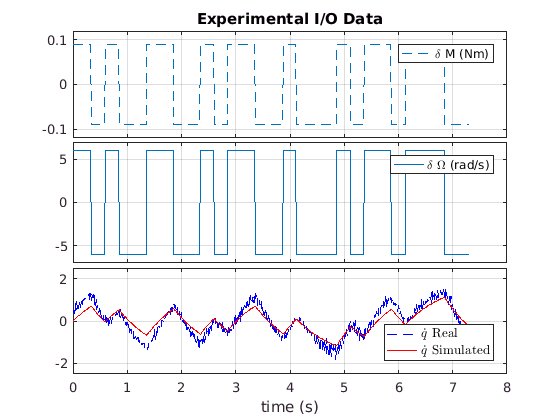

figure()
    subplot 311
        plot(vrft_data.time, vrft_data.dM, '--'); 
        legend('\delta M (Nm)'); ylim([-.12, .12]);
        title('Experimental I/O Data');
        
    subplot 312 
        plot(vrft_data.time, vrft_data.dOmega); 
        legend('\delta \Omega (rad/s)'); ylim([-7, 7]);
    subplot 313
        plot(vrft_data.time, vrft_data.q, '--b', ...
             vrft_data.time, vrft_data.q_sim, 'r'); 
        legend({'$$\dot{q}$$ Real', '$$\dot{q}$$ Simulated'}, ...
            'Location', 'southEast', 'Interpreter', 'latex', 'FontSize', 10); 
        xlabel('time (s)'); ylim([-2.5, 2.5]);
condense_subplots('tight', true)        

We are most interested in the third plot. This plot shows the real (measured) angular velocity ($\dot{q}$) and the simulatedangular velocity. These two values seem to be in accordance. So far, so good.

## Producing the VRFT controller

Note: `VRFT1_ry_theta` is an extension of the `VRFT1_ry` method that also exposes the value of the parameter vector. The only changes from the original file are related to this. 

We need to account for the fact that the data is noisy. This is done by setting $k$, the complexity of the ARX model used to estimate the noise. We use an experimental procedure for this and simply pick the value that minimises the overshoot. For a bandwidth of $10\ rad/s$ we have a k value of 6 for example.

% Note: We discard the actual controller tf since we may need to correct the pid gains
% [~, inner_pid_params_orig] = ...
%     VRFT1_ry_theta(vrft_data.dM, vrft_data.q, InnerReferenceModel_dt, ...
%                    PIDControllerClass_dt, [], OptimalNoiseOrder, []);
[~, inner_pid_params_orig] = ...
    VRFT1_ry_theta(vrft_data.dM, vrft_data.q, InnerReferenceModel_dt, ...
                   PIDControllerClass_dt, [], [17 7], []);

Reference to non-existent field 'q_dot'.


% [test, inner_pid_params_orig] = ...
%     VRFT1_ry_theta(vrft_data.dM, vrft_data.q, InnerReferenceModel_dt, ...
%                    PIDControllerClass_dt, [], [], []);

Occasionally the VRFT will produce a controller with a negative $K_d$ term wich we need to correct:

fprintf('PID Controller params: Kp = %.3f, Ki = %.3f, Kd = %.3f', ...
    inner_pid_params_orig(1), inner_pid_params_orig(2), inner_pid_params_orig(3));

inner_pid_params = [ 
    max(inner_pid_params_orig(1), 0) 
    max(inner_pid_params_orig(2), 0)
    max(inner_pid_params_orig(3), 0)
];

if abs(inner_pid_params(3)) < .0001
    inner_pid_params(3) = 0;
end

OptimalInnerController_dt = pid(...
    inner_pid_params(1), inner_pid_params(2), inner_pid_params(3), Tf, Ts);
fprintf('Corrected PID Controller params: Kp = %.3f, Ki = %.3f, Kd = %.3f', ...
    inner_pid_params(1), inner_pid_params(2), inner_pid_params(3));

## Viewing the Results

We now have a transfer function for the controller. The test harness for the quadcopter is continuous time so we need to move this controller to continuous time too. However we will keep the discrete-time models as a safety check.

First we calculate the discrete-time, closed-loop complementary sensitivty function

cloop = loopsens(PlantModel_dt, OptimalInnerController_dt); 
InnerLoop_VRFT_dt = cloop.Ti;

Next we discretise the controller and calculate the continuous-time, closed loop complemetary sensitivity function

OptimalInnerController = d2c(OptimalInnerController_dt); 
OptimalInnerController = pid(inner_pid_params(1), inner_pid_params(2), inner_pid_params(3));

cloop = loopsens(PlantModel, OptimalInnerController);
InnerLoop_VRFT = cloop.Ti;

To ensure that nothing has gone wrong we compare the outputs of the two controllers and the two systems

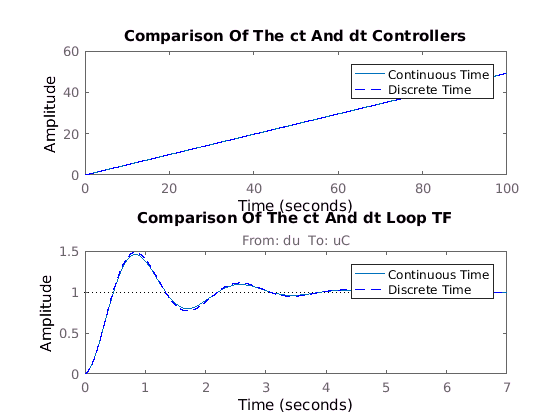

figure()
    subplot(2, 1, 1);
        step(OptimalInnerController, OptimalInnerController_dt, '--');
        legend('Continuous Time', 'Discrete Time');
        title('Comparison Of The ct And dt Controllers');
    subplot(2, 1, 2);
        step(InnerLoop_VRFT, InnerLoop_VRFT_dt, '--');
        legend('Continuous Time', 'Discrete Time');
        title('Comparison Of The ct And dt Loop TF');

## Performance Analysis

If the continuous and discrete time systems show no meaningful differences we can proceed with the analysis.

First step: look at the the difference between the reference model and the actual closed loop plant we get

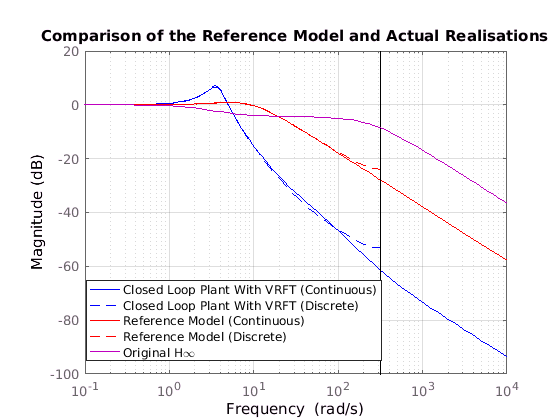

figure()
    bode(InnerLoop_VRFT, 'b', InnerLoop_VRFT_dt, 'b--', ...
         InnerReferenceModel, 'r', InnerReferenceModel_dt, 'r--', ...
         InnerLoop_Hinf, 'm', bode_no_phase);
    title('Comparison of the Reference Model and Actual Realisations');
    legend({ 'Closed Loop Plant With VRFT (Continuous)'
             'Closed Loop Plant With VRFT (Discrete)'
             'Reference Model (Continuous)'
             'Reference Model (Discrete)'
             'Original H\infty'
           }, 'location', 'SouthWest');
    grid on;

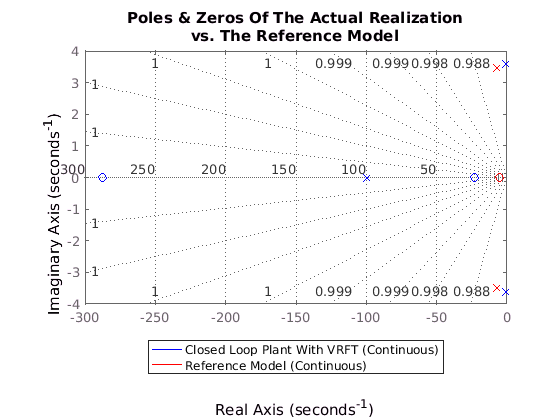

    
figure()
    pzmap(InnerLoop_VRFT, 'b', InnerReferenceModel, 'r');
    title({'Poles & Zeros Of The Actual Realization' 'vs. The Reference Model'});
    legend({ 'Closed Loop Plant With VRFT (Continuous)', 
             'Reference Model (Continuous)' }, 'location', 'SouthOutside');
    grid on;

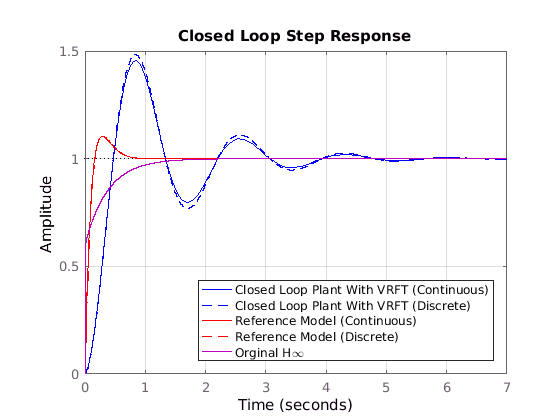

    
figure()
    step(InnerLoop_VRFT, 'b', InnerLoop_VRFT_dt, 'b--', ...
         InnerReferenceModel, 'r', InnerReferenceModel_dt, 'r--', ...
         InnerLoop_Hinf, 'm');
    title('Closed Loop Step Response'); 
    legend({ 'Closed Loop Plant With VRFT (Continuous)'
             'Closed Loop Plant With VRFT (Discrete)'
             'Reference Model (Continuous)'
             'Reference Model (Discrete)'
             'Orginal H\infty'
           }, 'location', 'SouthEast');
    grid on;       

## Conclusion

It seems that the continuous and discrete time realisations of the transfer functions are close enough to be interchangeable for our purposes. The PID parameters of the continuous and discrete time controllers are:

% No Tf term since the derivative action is 0 by definition
[Kp, Ki, Kd] = piddata(OptimalInnerController);
    
fprintf('PID Controller Parameters');

PID Controller Parameters

fprintf('');
fprintf('╔═════════════════════════╦══════════╦══════════╦══════════╗');

╔═════════════════════════╦══════════╦══════════╦══════════╗

fprintf('║                         ║    Kp    ║    Ki    ║    Kd    ║');

║                         ║    Kp    ║    Ki    ║    Kd    ║

fprintf('╠═════════════════════════╬══════════╬══════════╬══════════╣');

╠═════════════════════════╬══════════╬══════════╬══════════╣

fprintf('║ Discrete-Time Original  ║ %8.4f ║ %8.4f ║ %8.4f ║', ... 
    inner_pid_params_orig(1), inner_pid_params_orig(2), inner_pid_params_orig(3));

║ Discrete-Time Original  ║   0.0180 ║   0.4922 ║  -0.0001 ║

fprintf('╠═════════════════════════╬══════════╬══════════╬══════════╣');

╠═════════════════════════╬══════════╬══════════╬══════════╣

fprintf('║ Discrete-Time Corrected ║ %8.4f ║ %8.4f ║ %8.4f ║', ... 
    inner_pid_params(1), inner_pid_params(2), inner_pid_params(3));

║ Discrete-Time Corrected ║   0.0180 ║   0.4922 ║   0.0000 ║

fprintf('╠═════════════════════════╬══════════╬══════════╬══════════╣');

╠═════════════════════════╬══════════╬══════════╬══════════╣

fprintf('║ Continuous Time         ║ %8.4f ║ %8.4f ║ %8.4f ║', Kp, Ki, Kd);

║ Continuous Time         ║   0.0180 ║   0.4922 ║  -0.0001 ║

fprintf('╚═════════════════════════╩══════════╩══════════╩══════════╝');

╚═════════════════════════╩══════════╩══════════╩══════════╝

There is one worrying thing however: the bandwidth of the reference model and the bandwidth of the closed loop system we obtain with the VRFT are very different. The `InnerLoop_VRFT` transfer function has one more zero than the reference model. Maybe that is the root cause of this difference ?

For conveience we have: 

fprintf('InnerReferenceModel information:');

InnerReferenceModel information:

damp(InnerReferenceModel)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -7.20e+00 + 3.49e+00i     9.00e-01       8.00e+00         1.39e-01    
 -7.20e+00 - 3.49e+00i     9.00e-01       8.00e+00         1.39e-01    



fprintf('InnerLoop_VRFT information:');

InnerLoop_VRFT information:

damp(InnerLoop_VRFT)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -9.21e-01 + 3.62e+00i     2.47e-01       3.73e+00         1.09e+00    
 -9.21e-01 - 3.62e+00i     2.47e-01       3.73e+00         1.09e+00    
 -9.97e+01                 1.00e+00       9.97e+01         1.00e-02    


For convenience we will save some of the data we used here. In the outer VRFT we will need access to the input and output signals we used to generate the inner controller. We will also keep a copy of the generated controller for obvious reasons.

save('quad_copter_models.mat', ...
    'inner_bw', 'inner_damp', 'pole_position', ...
    'PlantModel', 'PlantModel_dt', ...
    'InnerReferenceModel', 'InnerReferenceModel_dt', ...
    'OptimalInnerController', 'OptimalInnerController_dt', ... 
    'InnerLoop_VRFT', 'InnerLoop_VRFT_dt', ...
    'vrft_data',  ...
    '-append' ...
);